%Exercise 1
CameraManGreyScale = imread('cameraman.tif');


%Exercise 2
[imgHeight, imgWidth] = size(CameraManGreyScale); %Without ;, size is shown

disp(imgHeight);

   256



disp(imgWidth);

   256



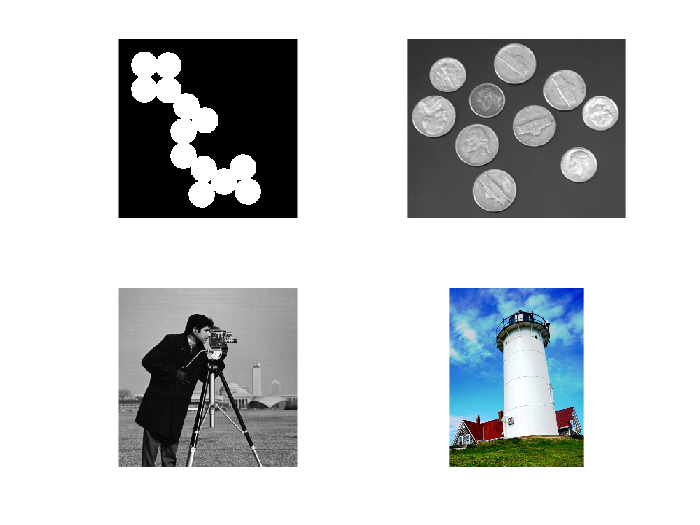


%Exercise 3

CoinsFigure = imread("coins.png");


figure;
hold on;
subplot(2,2,1);
imshow("circles.png");
subplot(2,2,2);
imshow(CoinsFigure);
subplot(2,2,3);
imshow(CameraManGreyScale);
subplot(2,2,4);
imshow("lighthouse.png");
hold off;

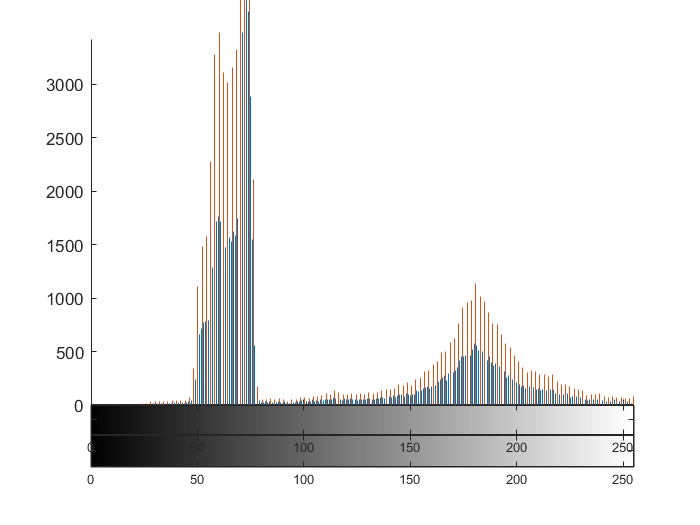



%Exercise 4  + 5 + 6
Coins = imread("coins.png");

figure; 
hold on;
imhist(Coins);
imhist(Coins, 128);
hold off;

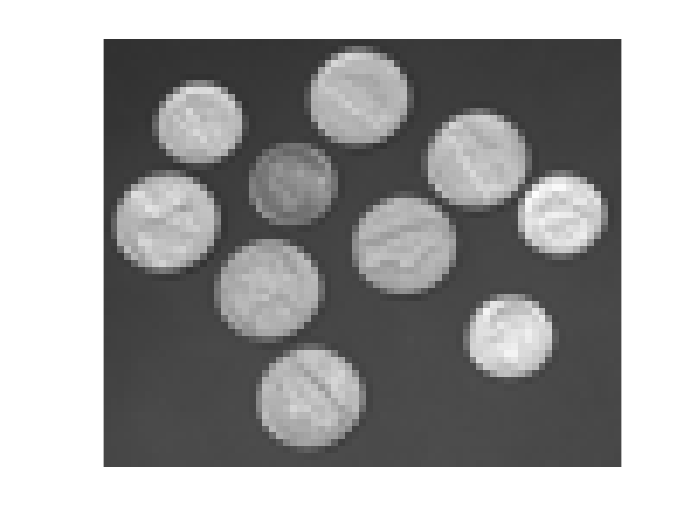


%Exercise 7
Coins_Resize = imresize(Coins, 0.25);
imshow(Coins_Resize);

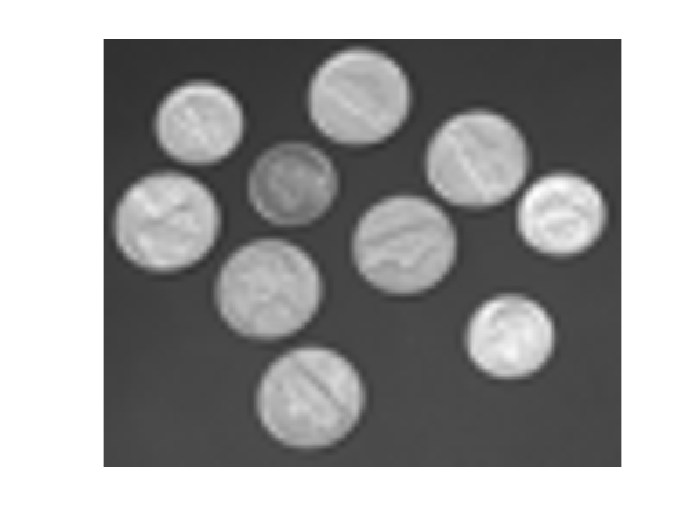


%Exercise 8
Coins_Resize_Big = imresize(Coins_Resize, 5);
imshow(Coins_Resize_Big);


%Exersize 9 
X = imresize(Coins, 3, 'Bilinear');
Y = imresize(Coins, 3, 'Nearest');

figure; 
hold on;
subplot(1,2,1);
imshow(X);
subplot(1,2,2);
imshow(Y);
hold off;

%Exercise 10

CoinsEQ = histeq(Coins);
imshow(CoinsEQ);

%Exercise 11
My_lighthouse = imread("lighthouse.png");

redChannel = My_lighthouse(:, :, 1);
greenChannel = My_lighthouse(:,:, 2);
blueChannel = My_lighthouse(:,:, 3);

figure; 
hold on;
subplot(1,3,1);
imshow(redChannel);
subplot(1,3,2);
imshow(greenChannel);
subplot(1,3,3);
imshow(blueChannel);
hold off;

%Exercise 12

HSV_lighthouse = rgb2hsv(My_lighthouse);

HueChannel = My_lighthouse(:, :, 1);
SatChannel = My_lighthouse(:,:, 2);
ValChannel = My_lighthouse(:,:, 3);

figure; 
hold on;
subplot(1,3,1);
imshow(HueChannel);
subplot(1,3,2);
imshow(SatChannel);
subplot(1,3,3);
imshow(ValChannel);
hold off;

%Exercise 13

YCbCR_lighthouse = rgb2ycbcr(My_lighthouse);

imshow(YCbCR_lighthouse);

%Exercise 14

LAB_lighthouse = rgb2lab(My_lighthouse);

imshow(LAB_lighthouse);










